# Trabalho de EE-254 (Controle Preditivo): Parte 2

**Observação:** Este trabalho deve ser realizado **sem o uso do MPT Toolbox.**

Considere o seguinte sistema de dois carros acoplados por uma mola:

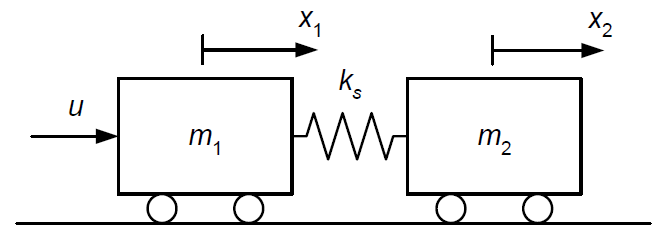

com deslocamentos $x_1$, $x_2$ definidos de modo que a mola esteja relaxada quando $x_1 = x_2$.  

A dinâmica deste sistema, a tempo contínuo, é descrita pelas seguintes equações:


$$m_1 \ddot{x}_1(t) = u(t) + k_s \big[\, x_2(t) - x_1(t) \,\big] $$



$$m_2 \ddot{x}_2(t) = - k_s \big[\, x_2(t) - x_1(t) \,\big]$$


que podem ser colocadas na forma 


$$\dot{x}(t) = A_c x(t) + B_c u(t) $$


com $x_3 = \dot{x}_1$, $x_4 = \dot{x}_2$ e

$A_c =
\left[
  \begin{array}{cccc}
    0 & 0 & 1 & 0 \\[4pt]
    0 & 0 & 0 & 1 \\[4pt]
    -k_s/m_1 & k_s/m_1 & 0 & 0 \\[4pt]
    k_s/m_2 & -k_s/m_2 & 0 & 0 \\
  \end{array}
\right]$, $B_c =
\left[
  \begin{array}{c}
    0 \\[4pt]
    0 \\[4pt]
    1/m_1 \\[4pt]
    0 \\
  \end{array}
\right]$

Neste trabalho, serão adotados os seguintes valores para os parâmetros do modelo:

$m_1 = 5$ kg, $m_2 = 3$ kg, $k_s = 10$ N/m, $g = 9\text{,}8$ m/s${}^2$

que resultam nas matrizes $A_c$, $B_c$ definidas no código abaixo:

clear, clc, close all
m1 = 5; m2 = 3; ks = 10; g = 9.8;
Ac = [0 0 1 0;
      0 0 0 1;
      -ks/m1 ks/m1 0 0;
      ks/m2 -ks/m2 0 0];
Bc = [0;0;1/m1;0];

Deseja-se conduzir o estado do sistema para a origem, partindo da seguinte condição inicial:


$$x(0) = \left[
\begin{array}{c}
-1 \text{ m}\\
-1 \text{ m}\\
0 \\
0 \\
\end{array}
\right]$$


Adicionalmente, deseja-se que a deformação da mola e o controle (ambos em módulo) não ultrapassem 0,05 m e 2 N, respectivamente.

O código abaixo obtém as matrizes $A$ e $B$ da equação de estado discretizada:


$$x(k+1) = A x(k) + B u(k)$$


considerando que o controle seja aplicado por meio de um segurador de ordem zero com período de amostragem $T = 0\text{,}2$ s.

T = 0.2;
[A,B] = c2dm(Ac,Bc,[],[],T,'zoh');

**Item a (4,0 pontos)** Considere um controlador DLQR com ganho $K$obtido da seguinte forma: 

q1 = 10; q2 = 10; q3 = 1; q4 = 1; q5 = 100;
Q = [q1 + q5 -q5 0 0; -q5 q2 + q5 0 0; 0 0 q3 0; 0 0 0 q4];
R = 1;
[K,P] = dlqr(A,B,Q,R);

lembrando que a matriz $P$ é a solução positivo-definida da equação algébrica de Riccati.

Empregando a função `determina_oinf.m` disponibilizada, obtenha o conjunto $\mathcal{O}_\infty = \{x : S_f x \leq b_f \}$ associado à dinâmica de malha fechada considerando as restrições de controle e estado impostas para a operação do sistema.

% Sf x < bf
Gamma = eye(4) ;
max_iter = 100 ;

b1 = 0.05

b1 = 0.0500

b2 = 2 

b2 = 2



xmin = [-b1; -b1; -b2; -b2]       

xmin =    -0.0500
   -0.0500
   -2.0000
   -2.0000


xmax = [b1; b1; b2; b2]

xmax =     0.0500
    0.0500
    2.0000
    2.0000


bx = [xmax; -xmin]

bx =     0.0500
    0.0500
    2.0000
    2.0000
    0.0500
    0.0500
    2.0000
    2.0000


Sx = [eye(4); -eye(4)]

Sx =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1
    -1     0     0     0
     0    -1     0     0
     0     0    -1     0
     0     0     0    -1


bpsi = bx;
Spsi = Sx;

[Sf_1, bf_1, Si_1, bi_1] = determina_oinf(A, Gamma, Spsi, bpsi, max_iter)

Iteração 1 / 100



%{
Gamma = eye(2) ;
xmin = [-b1; -b2]
xmax = [b1; b2]
bx = [xmax; -xmin]
Sx = [eye(2); -eye(2)]
bpsi = bx;
Spsi = Sx;
[Sf_2, bf_2, Si_2, bi_2] = determina_oinf(A, Gamma, Spsi, bpsi, max_iter)
%}


**Observação:** Caso não tenha sido possível completar este item, carregue o arquivo `oinf.mat` disponibilizado.

#### Item b (2,0 pontos)

Elabore um código para mostrar que $x(0) \neq \mathcal{O}_\infty$.

**Dica:** Basta mostrar que nem todas as linhas da desigualdade $S_f x(0) \leq b_f$ são satisfeitas.

x0 = [-1;-1;0;0]; % Condição inicial

max_iter = 100 ;

b1 = 0.05
b2 = 2 

x1 = [-b1; -b1; b1; b1] 
x2 = [-b2; b2; b2; b2]

file = load('oinf.mat');
Sf = file.Sf;
bf = file.bf;



m = Sf * x1
[rows, columns] = size(m)

%{
verificar se o resultado da multiplicacao de matrizes respeita as restrições
[s11 s12][x1*] <= [b1]
[s21 s22][x2*] <= [b2]

s11*x1+s12*x2<= b1
e
s21*x1+s22*x2<= b2
com
x1=x1* e x2=x2*
%}   

 fprintf('element >= %d', b1)

for i = 1:rows
    for j = 1:columns
        
        element = m(i,j);
        if element > b1
           fprintf('element %d, %d = %d \n ', i, j, element)
        end

    end
end

m = Sf * x2
[rows, columns] = size(m)
 fprintf('element >= %d', b2)

for i = 1:rows
    for j = 1:columns
        
        element = m(i,j);
        if element > b2
           fprintf('element %d, %d = %d \n ', i, j, element)
        end

    end
end




#### Item c (4,0 pontos)

Complete o código abaixo para simular o sistema em malha fechada empregando a lei de controle preditivo apresentada na Aula 8. Para isso, sugere-se empregar a função dlqrcon`.m` disponibilizada.

N = 15; % Horizonte de controle a ser adotado
x{1} = x0;
sys = ss(Ac,Bc,[],[]);
trec = 0; xrec = x{1}'; 
xbar = zeros(4,1); ubar = 0;
nt = 10; kf = 100; warning off

t = 0:nt:kf; % Vetor de tempo
u = zeros(1, kf); % 1 sinal de controle, cada coluna representa um tempo
y = zeros(1, kf); 


% u(k) = un(1);

% considerando eq de saída da forma y(t)=C.x(t)

C = [0 1 0 0];

k=1;
while (max(Sf*x{1} - bf) > 0)
    un = dlqrcon(A, B, Q, R,P,N, Sx, bx, Sf, bf, x{k}, xbar, ubar);
    u(k) = un(1);
    x{k+1} = A*x{x} + B*u(k);
    k=k+1;
end

kf = k;

for k = 1:kf-1  
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Insira linhas de código aqui para obter u{k} com base em x{k} %

    u(k) = ubar - K*(x{k} - xbar) 
    x{k+1} = A*x{k} + B*u(k);
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    t = linspace((k-1)*T,k*T,nt);
    %U = repmat(u{k}',nt,1);
    U = repmat(u(k)',nt,1);
    [~,tout,xout] = lsim(sys,U,t,x{k});
    trec = [trec;tout(2:end)];
    xrec = [xrec;xout(2:end,:)];
    x{k+1} = xrec(end,:)';
    
    y(k) = C * x(:, k);
end


S = stepinfo(y,t,1,0,'RiseTimeLimits',[0.1,0.9]);
RiseTime = S.RiseTime;

% Gráfico dos deslocamentos
figure
yrec = xrec(:,2);
h = plot(trec,xrec(:,1),trec,xrec(:,2)); 
set(h,'LineWidth',2), grid
hold on
xline(RiseTime,'--black');
text(RiseTime,0,['Rise time: ',num2str(round(RiseTime,2)),' s'],'HorizontalAlignment','right','VerticalAlignment','bottom');
xlabel('t / s'), ylabel('Deslocamento / m')
title('Output y(t)');
legend('x_1(t)', 'x_2(t)')



% Gráfico da deformação da mola
figure
h = plot(trec,xrec(:,1)-xrec(:,2));
set(h,'LineWidth',2), grid
xlabel('t / s'), ylabel('(x_1(t) - x_2(t)) / m')


% Gráfico do controle
figure
h = stairs([0:kf]*T,[cell2mat(u) u{end}]);
set(h,'LineWidth',2)
xlabel('t / s'), ylabel('u(t) / N')
title('Spring deformation: x1(t) - x2(t)');
